## Zadanie 1

% Prosi użytkownika o Tmin i Tmax
Tmin = input('Podaj Tmin: ');
Tmax = input('Podaj Tmax: ');

% Tworzy wektor Celsjusz
Celsjusz = Tmin:1:Tmax;

% Zapisuje do pliku
writematrix(Celsjusz, 'celsjusze.csv', 'Delimiter', ';');

% Czyści zmienne
clear;

% Wczytuje zmienne z pliku
Celsjusz = readmatrix('celsjusze.csv', 'Delimiter', ';');

% Tworzy wektor Kelwiny
Kelwiny = Celsjusz + 273.15;

% Wyświetla wynik
disp('Wektor Kelwiny:');

Wektor Kelwiny:


disp(Kelwiny);

  223.1500  224.1500  225.1500  226.1500  227.1500  228.1500  229.1500  230.1500  231.1500  232.1500  233.1500  234.1500  235.1500  236.1500  237.1500  238.1500  239.1500  240.1500  241.1500  242.1500  243.1500  244.1500  245.1500  246.1500  247.1500  248.1500  249.1500  250.1500  251.1500  252.1500  253.1500  254.1500  255.1500  256.1500  257.1500  258.1500  259.1500  260.1500  261.1500  262.1500  263.1500  264.1500  265.1500  266.1500  267.1500  268.1500  269.1500  270.1500  271.1500  272.1500  273.1500  274.1500  275.1500  276.1500  277.1500  278.1500  279.1500  280.1500  281.1500  282.1500  283.1500  284.1500  285.1500  286.1500  287.1500  288.1500  289.1500  290.1500  291.1500  292.1500  293.1500  294.1500  295.1500  296.1500  297.1500  298.1500  299.1500  300.1500  301.1500  302.1500  303.1500  304.1500  305.1500  306.1500  307.1500  308.1500  309.1500  310.1500  311.1500  312.1500  313.1500  314.1500  315.1500  316.1500  317.1500  318.1500  319.1500  320.1500  321.1500  322.1500

## Zadanie 2

function koszt = wypozyczRower(h)
    if h <= 2
        koszt = h * 5;
    elseif h <= 5
        koszt = 2 * 5 + (h - 2) * 2;
    else
        koszt = 2 * 5 + 3 * 2 + (h - 5) * 1;
    end
end

## Zadanie 3

function [s1, s2] = sumujWartosci(n)
    % Generuje wektor pseudolosowy
    wektor = rand(1, n);
    
    % Suma za pomocą pętli for
    s1 = 0;
    for i = 1:n
        s1 = s1 + wektor(i);
    end
    
    % Suma za pomocą wbudowanej funkcji
    s2 = sum(wektor);
end

## Zadanie 4

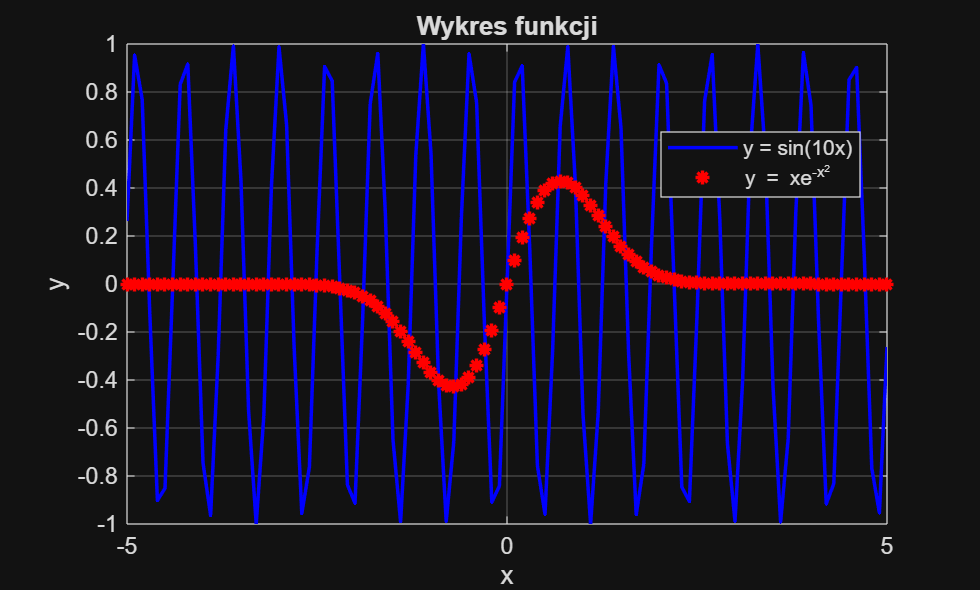

x = -5:0.1:5;

% Funkcje
y1 = sin(10 * x);
y2 = x .* exp(-x.^2);

% Tworzenie wykresu
plot(x, y1, 'b-', 'LineWidth', 1.5);
hold on;
plot(x, y2, 'r*', 'LineWidth', 1.5);
hold off;

% Dodanie legendy i opisów osi
legend('y = sin(10x)', 'y = xe^{-x^2}', 'Location', 'Best');
xlabel('x');
ylabel('y');
title('Wykres funkcji');
grid on;

## Zadanie 5

% Prosi użytkownika o m
m = input('Podaj wymiar macierzy m: ');

% Generuje macierz pseudolosową
M = rand(m, m);

% Zapisuje macierz do pliku
save('losowa.mat', 'M');

% Czyści zmienne
clear;

% Wczytuje zmienne z pliku
load('losowa.mat', 'M');

% Oblicza ślad macierzy
slad = trace(M);

% Wyświetla wynik
disp(['Ślad macierzy: ', num2str(slad)]);

Ślad macierzy: 3.5213


## Zadanie 6

function sortuj(wekt)
    if wekt(1) > 0
        disp('Posortowany wektor rosnąco:');
        disp(sort(wekt));
    elseif wekt(1) < 0
        disp('Posortowany wektor malejąco:');
        disp(sort(wekt, 'descend'));
    else
        disp('Pierwszy element równy 0');
    end
end

## Zadanie 7

function pierwiastki(n)
    for i = 1:2:n
        fprintf('Pierwiastek z %d wynosi %.2f\n', i, sqrt(i));
    end
end

## Zadanie 8

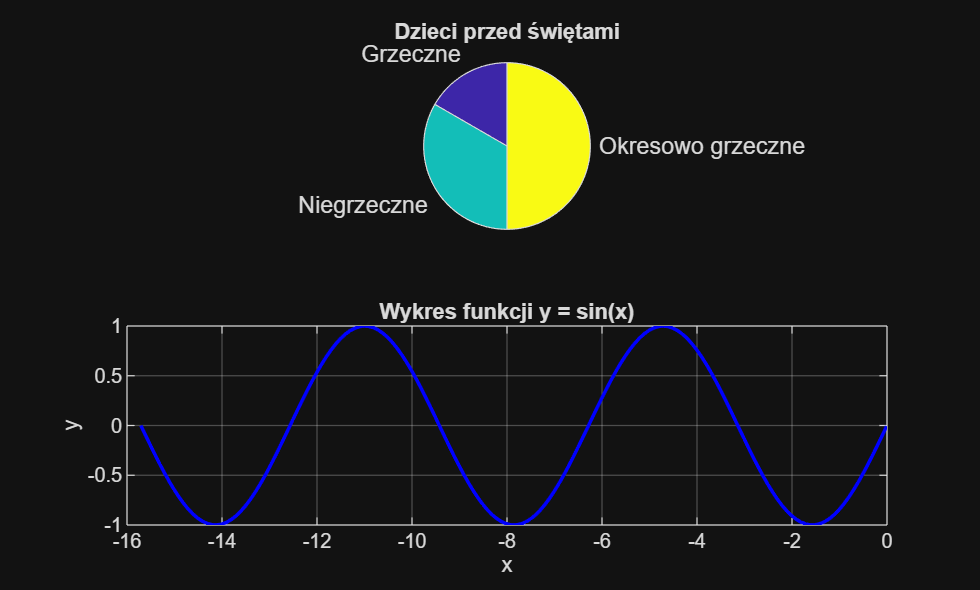

% Dane do wykresu ciasteczkowego
etykiety = {'Grzeczne', 'Niegrzeczne', 'Okresowo grzeczne'};
ilosci = [100, 200, 300];

% Tworzenie okna graficznego z dwoma wykresami
figure;

% Wykres ciasteczkowy
subplot(2, 1, 1);
pie(ilosci, etykiety);
title('Dzieci przed świętami');

% Wykres funkcji sinus
x = -5*pi:0.1:0;
y = sin(x);

subplot(2, 1, 2);
plot(x, y, 'b-', 'LineWidth', 1.5);
xlabel('x');
ylabel('y');
title('Wykres funkcji y = sin(x)');
grid on;